folder = root_dir + "/" + testdate + "/uav_data/*.csv";

files = dir(folder);
display(files)

files = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


file_num = 2; %start at 3
file_name = files(file_num).folder + "/" + files(file_num).name;
% file = importdata(file_name,',');
% uav_data = file.data(file.data(:,1) < 2000000, :);

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["time", "gx", "gy", "gz", "ax", "ay", "az", "ign"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
uav_data = readtable(file_name, opts);

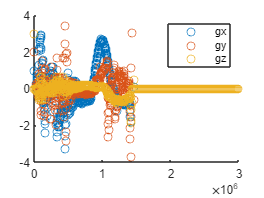

clf
hold on
ylim([-4 4])
scatter(uav_data{:,1}, uav_data{:,2})
scatter(uav_data{:,1}, uav_data{:,3})
scatter(uav_data{:,1}, uav_data{:,4})
legend(uav_data.Properties.VariableNames(2:4))
hold off

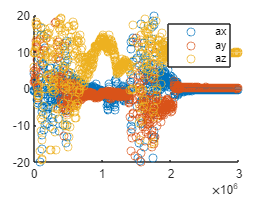

clf
hold on
ylim([-20 20])
scatter(uav_data{:,1}, uav_data{:,5})
scatter(uav_data{:,1}, uav_data{:,6})
scatter(uav_data{:,1}, uav_data{:,7})
legend(uav_data.Properties.VariableNames(5:7))
hold off

% histogram(1000000./diff(data(:,1)), 100)

% 
% ifilt = imufilter('SampleRate', 333);
% for ii=1:size(imu_data,1)
%     qimu = ifilt(imu_data(ii,5:7), imu_data(ii,2:4));
%     set(poseplot, "Orientation", qimu)
%     drawnow limitrate
% end

imu_data = uav_data;
ifilt = imufilter('SampleRate', 333, 'LinearAccelerationDecayFactor', 0.85);
a = ifilt(imu_data{:,5:7}, imu_data{:,2:4});

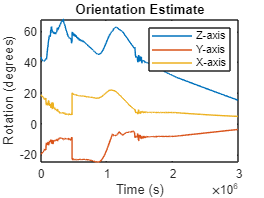


time_imu = (0:1:size(imu_data,1)-1)/333;
orientation = eulerd(a,'XYZ','frame');
plot(uav_data{:,1},orientation)
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

az = imu_data{:,5};
ax = imu_data{:,6};
ay = imu_data{:,7};

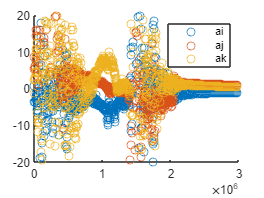

az_abs = imu_data{:,5} - (9.81 * tand(orientation(:,3)));
ax_abs = imu_data{:,6} - (9.81 * tand(orientation(:,2)));
ay_abs = imu_data{:,7} - (9.81 * cosd(orientation(:,1)));
clf
hold on
ylim([-20 20])
scatter(uav_data{:,1}, az_abs, 'DisplayName', "ai")
scatter(uav_data{:,1}, ax_abs, 'DisplayName', "aj")
scatter(uav_data{:,1}, ay_abs, 'DisplayName', "ak")
hold off
legend

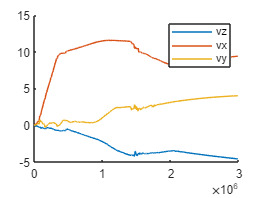

clf
vz = cumtrapz(uav_data{:,1}./1e6, az_abs);
vx = cumtrapz(uav_data{:,1}./1e6, ax_abs);
vy = cumtrapz(uav_data{:,1}./1e6, ay_abs);
hold on
plot(uav_data{:,1}, vz, 'DisplayName', "vz")
plot(uav_data{:,1}, vx, 'DisplayName', "vx")
plot(uav_data{:,1}, vy, 'DisplayName', "vy")
hold off
legend

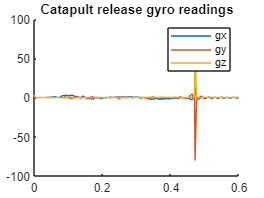

clf
hold on
title("Catapult release gyro readings")
xlim([0,0.6])
plot(uav_data{:,1}/1e6, uav_data{:,2})
plot(uav_data{:,1}/1e6, uav_data{:,3})
plot(uav_data{:,1}/1e6, uav_data{:,4})
legend(uav_data.Properties.VariableNames(2:4))
hold off

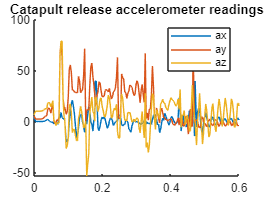

clf
hold on
title("Catapult release accelerometer readings")
xlim([0,0.6])
plot(uav_data{:,1}/1e6, uav_data{:,5})
plot(uav_data{:,1}/1e6, uav_data{:,6})
plot(uav_data{:,1}/1e6, uav_data{:,7})
legend(uav_data.Properties.VariableNames(5:7))
hold off

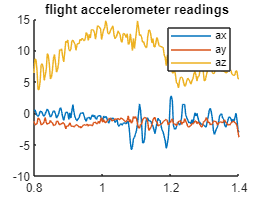

clf
hold on
title("flight accelerometer readings")
xlim([0.8,1.4])
plot(uav_data{:,1}/1e6, uav_data{:,5})
plot(uav_data{:,1}/1e6, uav_data{:,6})
plot(uav_data{:,1}/1e6, uav_data{:,7})
legend(uav_data.Properties.VariableNames(5:7))
hold off

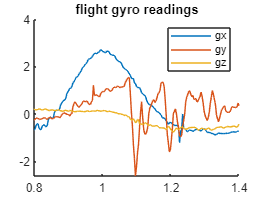

clf
hold on
title("flight gyro readings")
xlim([0.8,1.4])
plot(uav_data{:,1}/1e6, uav_data{:,2})
plot(uav_data{:,1}/1e6, uav_data{:,3})
plot(uav_data{:,1}/1e6, uav_data{:,4})
legend(uav_data.Properties.VariableNames(2:4))
hold off